% Variables
syms theta x

% constants
syms Kt Ke R mu_m
syms M L r g

% Continous state space model

A_c = [0, 1, 0, 0;
       g/L, 0, 0, 0;
       0, 0, 0, 1;
       -g, 0, 0, -mu_m/(M*R*r)]

$$A\_c = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ \frac{g}{L} & 0 & 0 & 0\\ 0 & 0 & 0 & 1\\ -g & 0 & 0 & -\frac{\mu_{m}}{M\,R\,r} \end{array}\right)$$


% A_c = [0, 1, 0;
%        g/L, 0, 0;
%        -g, 0, -mu_m/(M*R*r)]

B_c = [0, 0;
     -Kt/(R*M*L^2), -Kt/(R*M*L^2);
     0, 0;
     Kt/(M*R*r), Kt/(M*R*r)]

$$B\_c = \left(\begin{array}{cc} 0 & 0\\ -\frac{\mathrm{Kt}}{L^{2}\,M\,R} & -\frac{\mathrm{Kt}}{L^{2}\,M\,R}\\ 0 & 0\\ \frac{\mathrm{Kt}}{M\,R\,r} & \frac{\mathrm{Kt}}{M\,R\,r} \end{array}\right)$$


% B_c = [0, 0;
%        -Kt/(R*M*L^2), -Kt/(R*M*L^2);
%        Kt/(M*R*r), Kt/(M*R*r)]

% C = [1, 0, 0, 0];

C = eye(4);

% Values
constants = [ Kt,   mu_m,  R,   M,   L,      r,     g  ];
values =    [0.23, 0.25, 3.5, 0.34, 0.04, 0.055/2, 9.82];

A_c = double(subs(A_c, constants, values))

A_c =          0    1.0000         0         0
  245.5000         0         0         0
         0         0         0    1.0000
   -9.8200         0         0   -7.6394


B_c = double(subs(B_c, constants, values))

B_c =          0         0
 -120.7983 -120.7983
         0         0
    7.0283    7.0283



n = size(A_c,1);
m = size(B_c,2);
p = size(C,1);

eigenvalues = eig(A_c); % Unstable system!

rank(obsv(A_c,C)); % 2, not fully observable

rank(ctrb(A_c,B_c)); % 4, controllable

% Discrete system:
Ts = 0.01;

sys = ss(A_c, B_c, C, 0);
dsys = c2d(sys,Ts);

A_d = dsys.A

A_d =     1.0123    0.0100         0         0
    2.4651    1.0123         0         0
   -0.0005   -0.0000    1.0000    0.0096
   -0.0949   -0.0005         0    0.9265


B_d = dsys.B

B_d =    -0.0061   -0.0061
   -1.2129   -1.2129
    0.0003    0.0003
    0.0679    0.0679



% LQR

% Weighting matricies
Q_lqr = diag([1000, 0, 1, 0]);
R_lqr = 0.001*eye(m);

[P, L, eigen] = idare(A_d, B_d, Q_lqr, R_lqr) % Calculate at startup

P = 1.0e+03 *

    1.1065    0.0007    0.0199    0.0026
    0.0007    0.0003    0.0413    0.0054
    0.0199    0.0413    5.4264    0.7085
    0.0026    0.0054    0.7085    0.0926


L =   -68.5211   -0.7666   -2.1343   -0.2793
  -68.5211   -0.7666   -2.1343   -0.2793


eigen =     0.9998
    0.9265
   -0.6100
   -0.0149


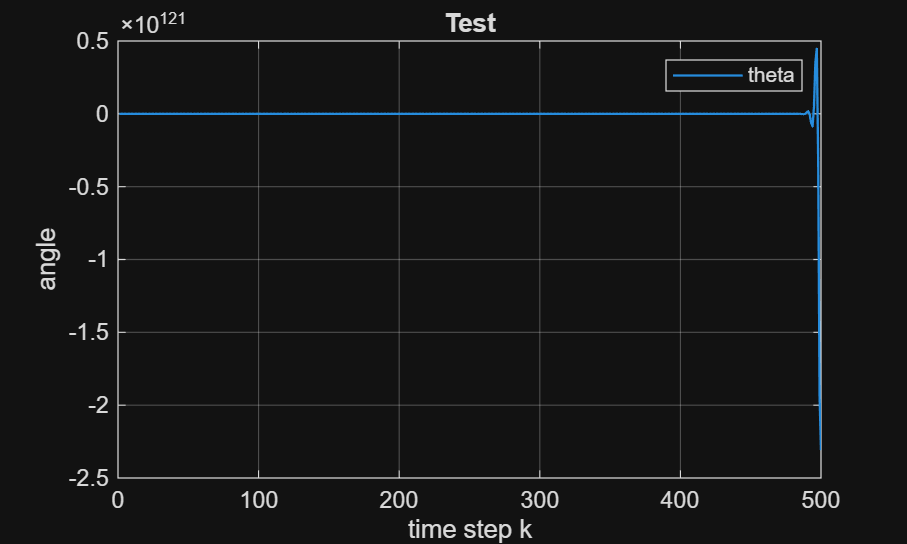


% Kalman

% Covariances
Q_kalm = diag([1, 1, 1, 1]);
R_kalm = eye(p);

% Initial state estimate and covariance
x0 = [0.1; 0; 0; 0];
P0 = eye(n);

% Set point
x_ref = [0; 0; 0; 0];

x_hat_pred = zeros(n,1);    % x_hat(k-1)    Predicted state
x_hat = zeros(n,1);         % x_hat(k)      Updated state estimate (correction)
u = zeros(m,1);             % Calculated input (voltage, [VR; VL])
y = zeros(p,1);             % Measurements

P_pred = P0;                % P(k-1)        Predicted covariance
P = zeros(n);               % P(k)          Current covariance

K = zeros(n);               % Current Kalman gain

x = x0;
x_next = zeros(n,1);
X = {zeros(n,1)};
U = {zeros(m,1)};

tf = 500;

for k = 1:tf

    % Simulation

    x_next = A_d*x + B_d*u;
    y = C*x;
    x = x_next;

    % Kalman gain
    K = P_pred * C.' * inv(C * P_pred * C.' + R_kalm);

    % Correction (measurement update)
    x_hat = x_hat_pred + K * (y - C * x_hat_pred);
    P = (eye(n) - K*C) * P_pred;  % Update error covariance

    % Prediction (a priori state estimate)
    x_hat_pred = A_d*x_hat + B_d*u;
    P_pred = A_d * P * A_d.' + Q_kalm;

    % Compute LQ control law
    x_dev = (x_hat - x_ref);
    u_dev = -L*x_dev;

    u = u_dev;

    X{k} = x;
    U{k} = u;
end

X_matrix = cell2mat(X);
U_matrix = cell2mat(U);

plotlen = tf;
figure(1);
plot(1:plotlen,X_matrix(1,1:plotlen),'Linewidth',1)
xlabel('time step k');
ylabel('angle');
title('Test');
legend('theta');
grid on;

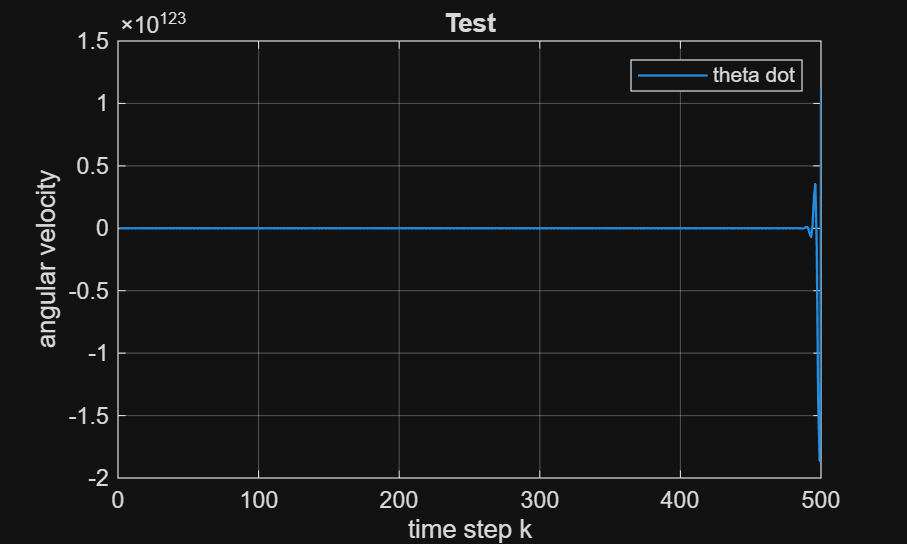


figure(2);
plot(1:plotlen,X_matrix(2,1:plotlen),'Linewidth',1)
xlabel('time step k');
ylabel('angular velocity');
title('Test');
legend('theta dot');
grid on;

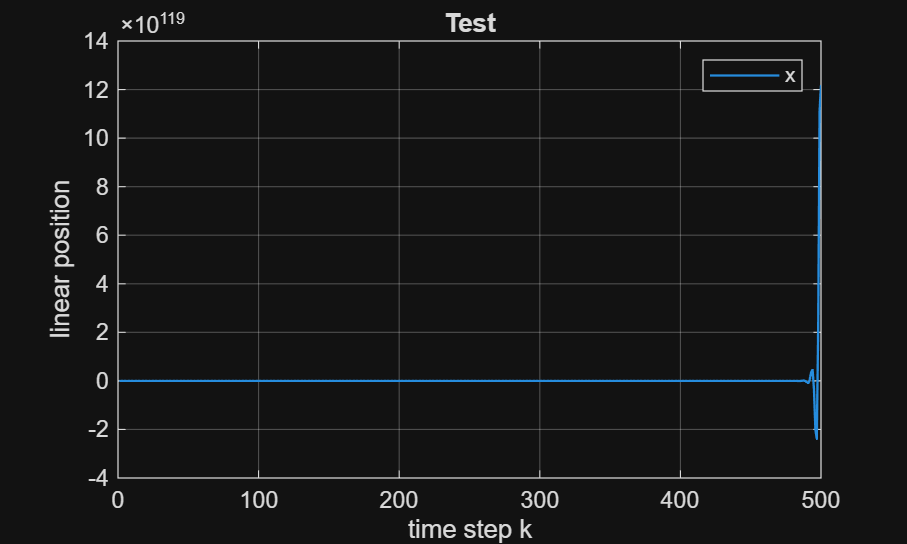


figure(3);
plot(1:plotlen,X_matrix(3,1:plotlen),'Linewidth',1)
xlabel('time step k');
ylabel('linear position');
title('Test');
legend('x');
grid on;

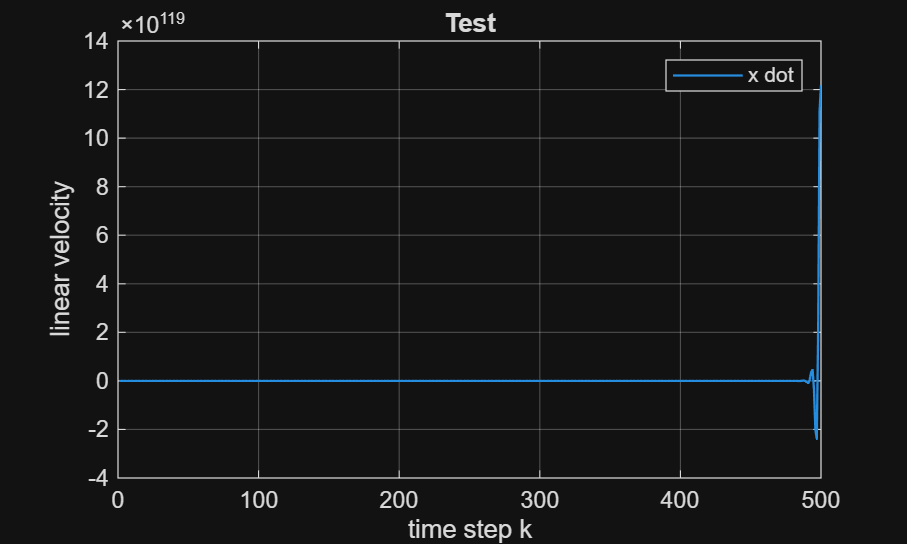


figure(4);
plot(1:plotlen,X_matrix(3,1:plotlen),'Linewidth',1)
xlabel('time step k');
ylabel('linear velocity');
title('Test');
legend('x dot');
grid on;

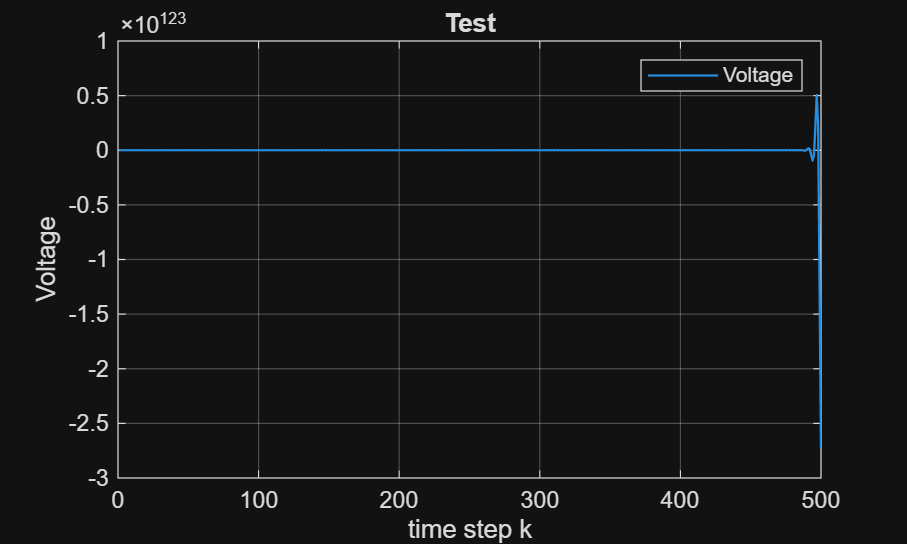


figure(5);
plot(1:plotlen,U_matrix(1,1:plotlen),'Linewidth',1)
xlabel('time step k');
ylabel('Voltage');
title('Test');
legend('Voltage');
grid on;